# Plotting 

## PLOT INDIVIDUAL GROUPS

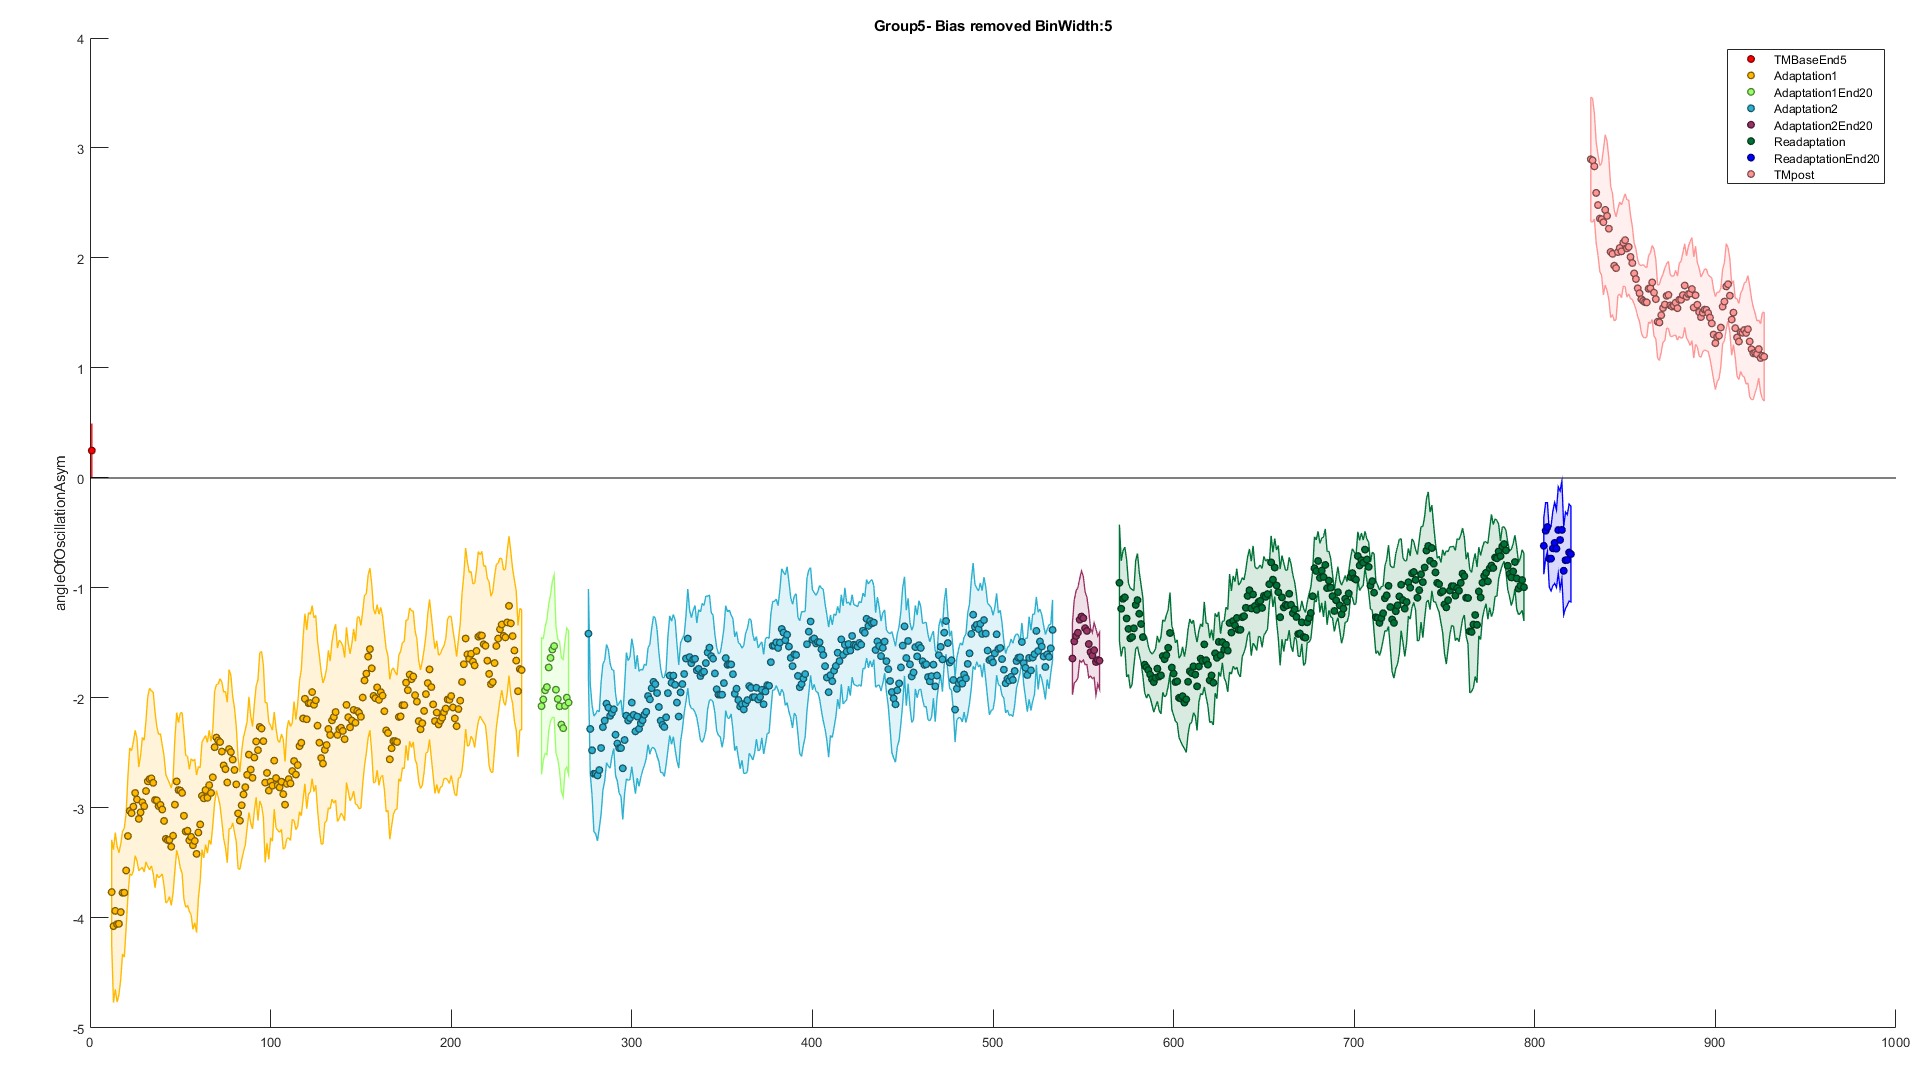

Type={'TM'};
% % close all
% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\GroupsSMatrix')
% cd(['C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix\Groups\Line'])
% cd(['C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix\Groups\Line\Line1'])
% cd(['C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix\Groups\hipPosition'])
% cd(['C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix\Groups'])
% cd(['C:\Users\maris\Desktop\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix\Groups\Line\Line1'])
% cd(['C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix\Groups\Line'])
% cd(['C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix\Line'])
cd(['C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix\Line'])



files=what('./'); 
fileList=files.mat;

for i=5  

group=num2str(fileList{i});
load(group)

binwidth=5; 
removeBias=1;
indvplot=0;
alignEndOG=5;
alignEnd=20;
alignIni=[];
TmBaseIni=5;
% parameters={'stepLengthAsym','netContributionNorm'};
% parameters={'spatialContributionNorm','stepTimeContributionNorm','velocityContributionNorm','netContributionNorm'};
% parameters={'phaseShift','angleOfOscillationAsym','netContributionNorm'};
parameters={'angleOfOscillationAsym'};
% parameters={'alphaAngSlow','alphaAngTemp','alphaAngFast','betaAngSlow','betaAngFast'};
% parameters={'spatialContribution','stepTimeContribution','velocityContribution','netContribution'};
% parameters={'alphaSlow','alphaFast'};
%  parameters={'alphaSlow','alphaFast','Xslow','Xfast'};
if strcmp(Type,'OG')
cond={'OGBase','OGpost'};
else
% cond={'TMBase','SomeBaseline','Adaptation1','Adaptation2','Catch','Readaptation','TMpost'};
% cond={'TMBase','Adaptation1','Adaptation2','Catch','Readaptation','TMpost'};
cond={'TMBase','Adaptation1','Adaptation2','Readaptation','TMpost'};
end
TimecourseDM(SMatrix,parameters,cond,binwidth,indvplot,removeBias,alignEndOG,alignIni,alignEnd,TmBaseIni);

% if removeBias && indvplot
%     print([group(1:end-4) 'IndvBiasAllStridesRemovedBinWidth' num2str(binwidth) parameters{1}],'-dpng')
% elseif indvplot
%     print([group(1:end-4) 'IndvBinWidth' num2str(binwidth) parameters{1}],'-dpng')
% elseif indvplot==0 && removeBias==1
%     print([group(1:end-4) 'BiasAllStridesRemovedBinWidth' num2str(binwidth) parameters{1}],'-dpng')
% elseif indvplot==0 && removeBias==0
%     print([group(1:end-4) 'BinWidth' num2str(binwidth) parameters{1}],'-dpng')
% end

end

## PLOT AVG GROUPS

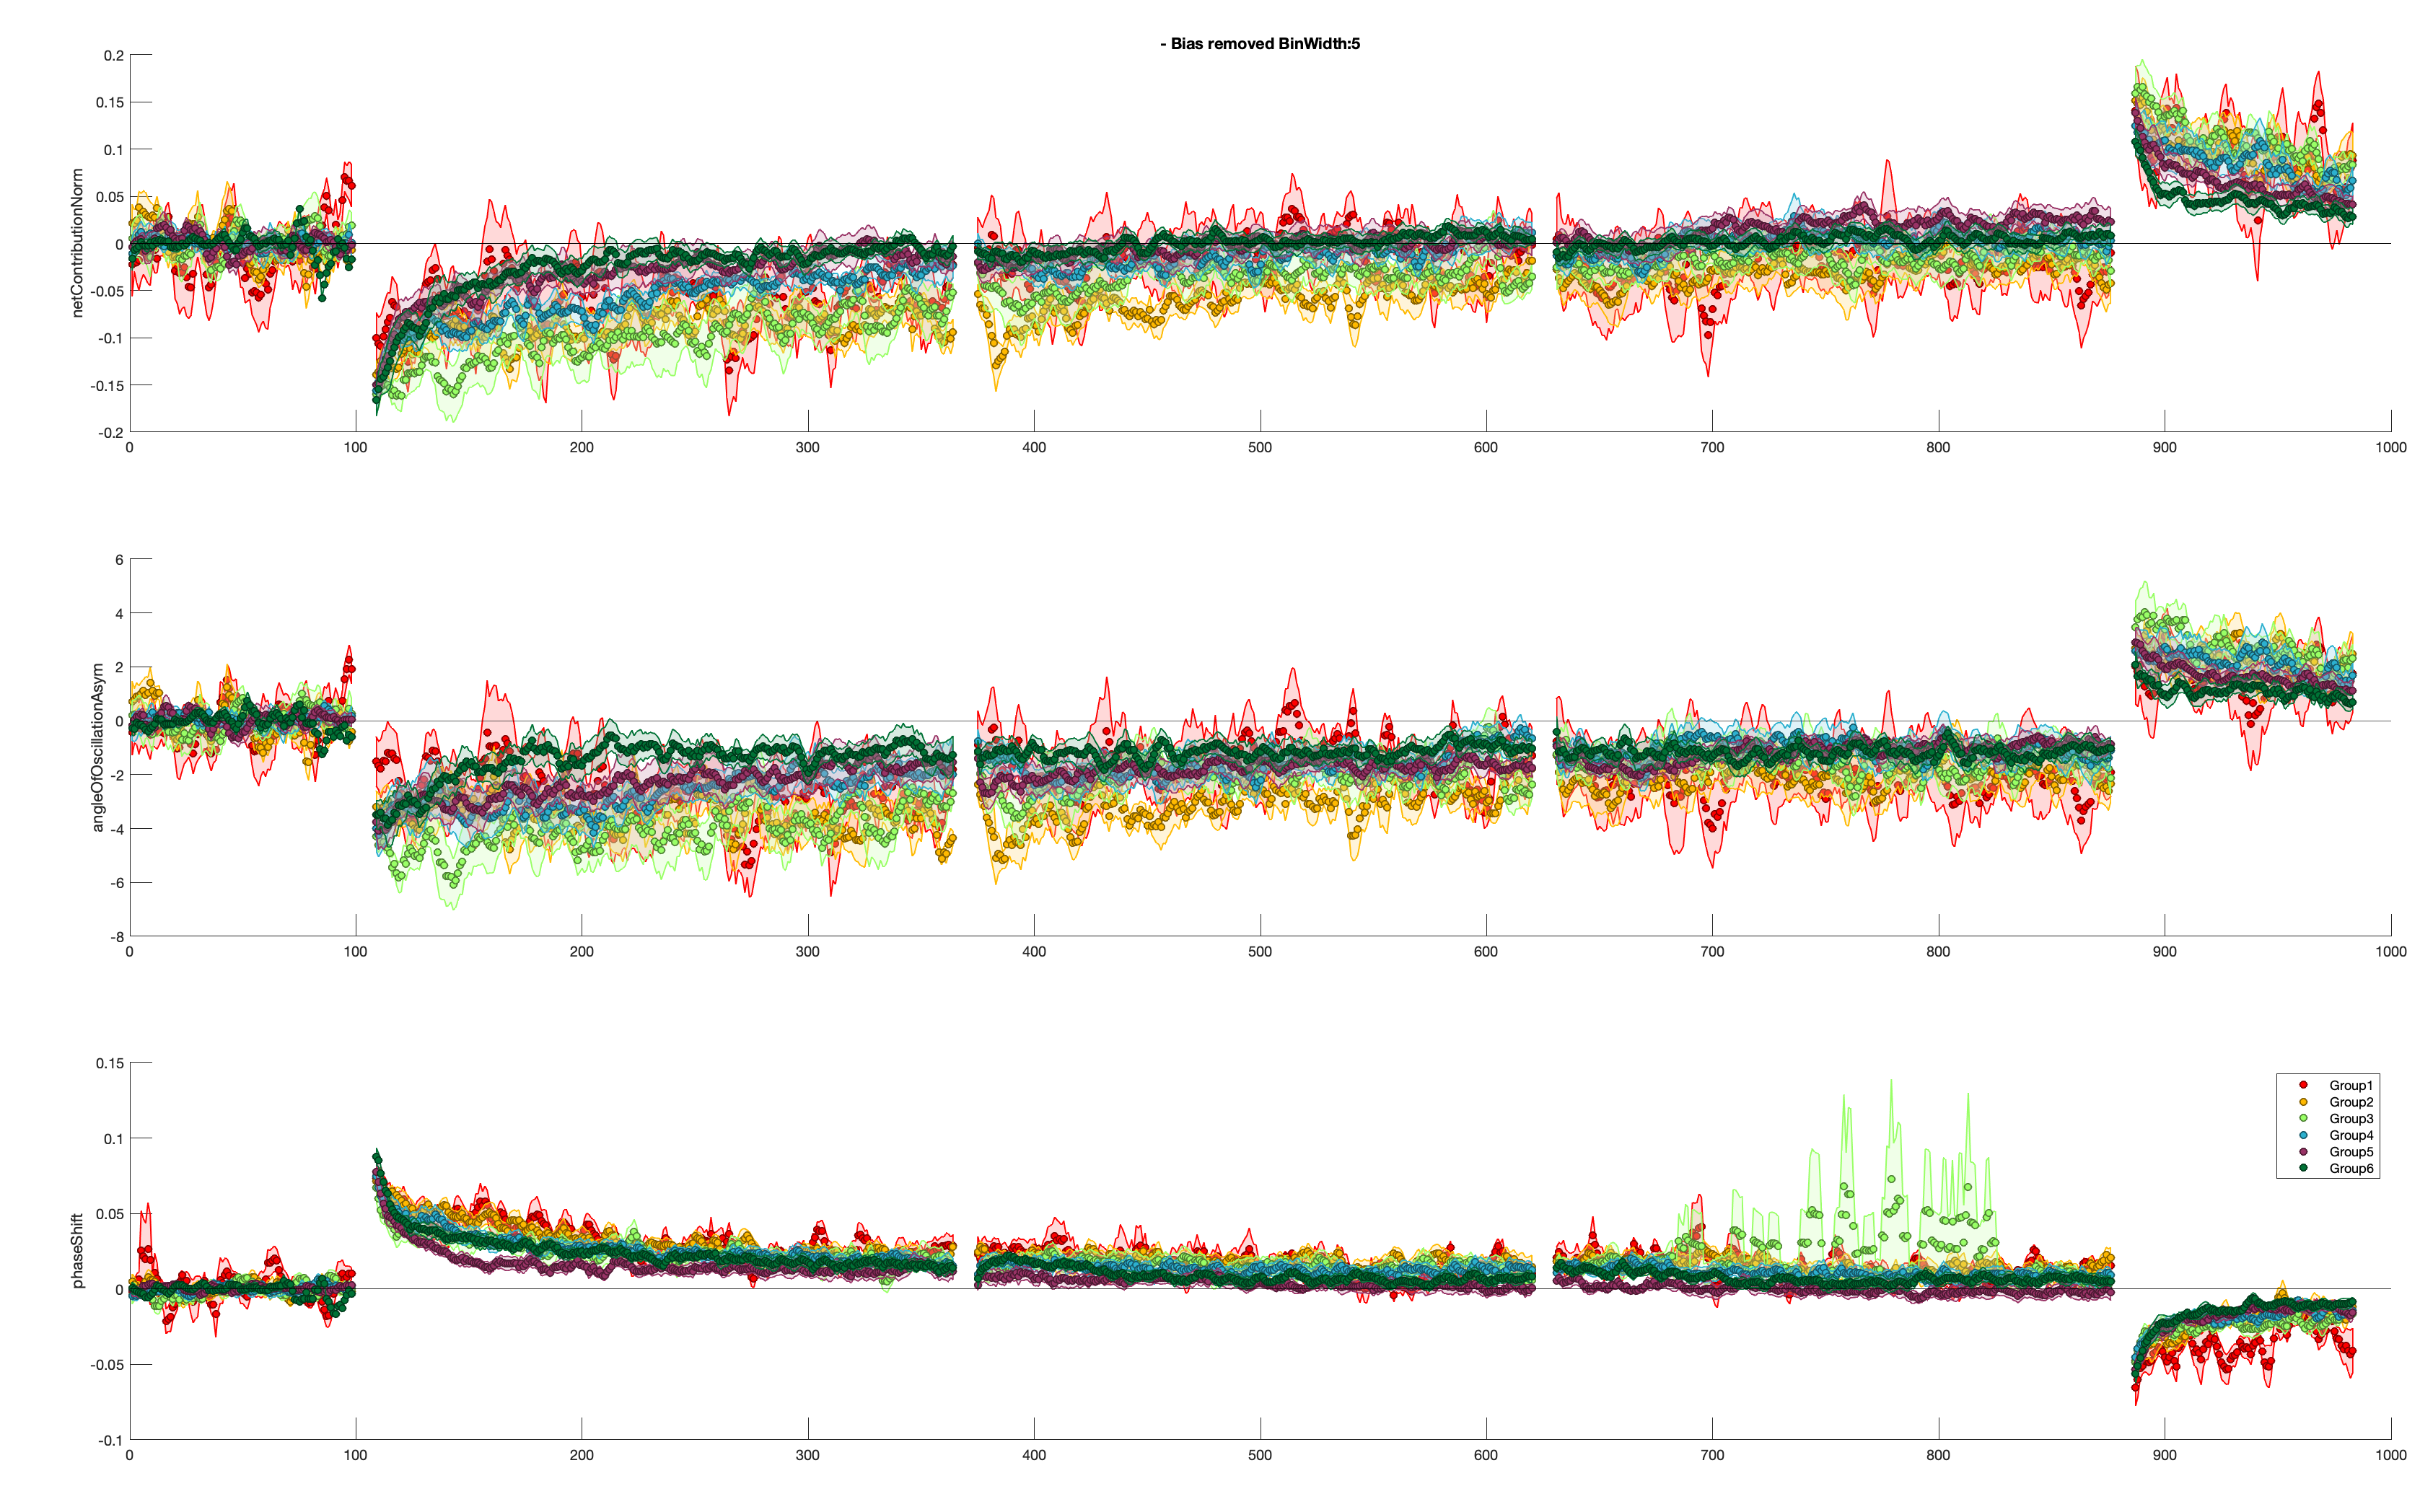

%This section plot average time courses gfor

Type={'TM'};
% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix')
% cd(['C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix'])
% cd(['C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix'])
% cd(['C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix'])

% files=what('./'); 
% fileList=files.mat;

% group=num2str(fileList{end});
% load(group)
binwidth=5;
removeBias=1;
alignEndOG=[];
alignEnd=[];
alignIni=[];
TmBaseIni=[];

% parameters={'stepLengthAsym','netContributionNorm'};
% parameters={'spatialContributionNorm','stepTimeContributionNorm','velocityContributionNorm','netContributionNorm'};
parameters={'netContributionNorm','angleOfOscillationAsym','phaseShift'};
% parameters={'alphaAngSlow','alphaAngTemp','alphaAngFast','betaAngSlow','betaAngFast'};
%  parameters={'alphaSlow','alphaFast'};
%  parameters={'alphaSlow','alphaFast','Xslow','Xfast'};
if strcmp(Type,'OG')
cond={'OGBase','OGpost'};
else
cond={'TMBase','Adaptation1','Adaptation2','Readaptation','TMpost'};
% cond={'Adaptation1'};
% cond={'TMBase','SomeBaseline','Adaptation1','Adaptation2','Catch','Readaptation','TMpost'};
end

TimecourseDM(SMatrix,parameters,cond,binwidth,0,removeBias,alignEndOG,alignIni,alignEnd,TmBaseIni);


% if removeBias
% print(['GroupsAvgBiasAllStridesRemovedBinWidth' num2str(binwidth) Type{1}],'-dpng')
% else
% print(['GroupsAvgBinWidth' num2str(binwidth) Type{1}],'-dpng')  
% end

## ALL CONDITIONS INDIVIDUAL AGE GROUP TIME COURSE

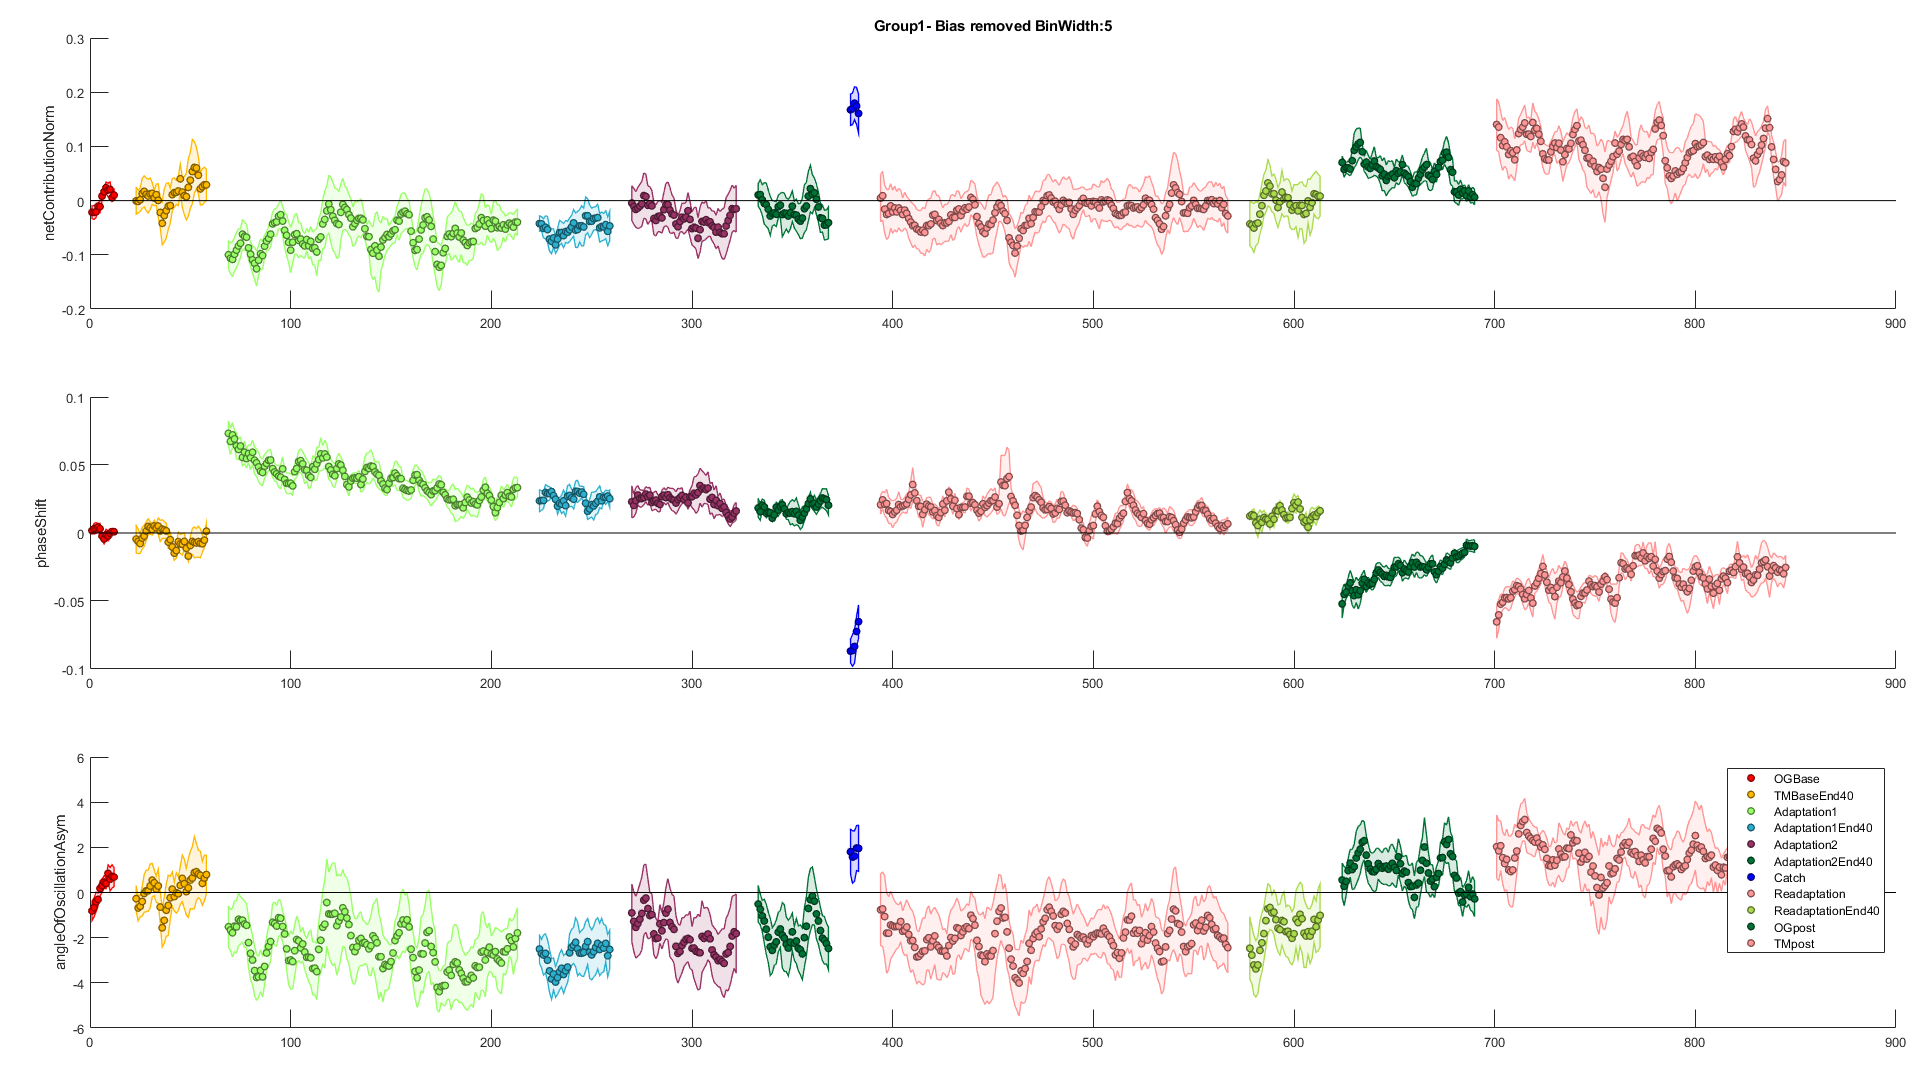

% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\ConcGRoups')
% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\ConcGRoups\hipPosition')
% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\ConcGRoups\Line')
% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\ConcGRoups')
% cd('C:\Users\maris\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcGRoups')
cd('C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLineAll\Groups')

files=what('./'); 
fileList=files.mat;

for i=1
    
group=num2str(fileList{i});
load(group)

binwidth=5;
removeBias=1;
indvplot=0;
alignEndOG=[];
alignEnd=[];
alignIni=[];
TmBaseIni=[];
alignEndOG=[];
alignEnd=40;
alignIni=[];
TmBaseIni=40;
parameters={'netContributionNorm','phaseShift','angleOfOscillationAsym'};
% parameters={'spatialContribution','stepTimeContribution','velocityContribution','netContribution'};
% parameters={'alphaSlow','alphaFast'};
% parameters={'netContributionNorm'};

% parameters={'alphaAngSlow','alphaAngTemp','alphaAngFast','betaAngSlow','betaAngFast'};
cond={'OGBase','TMBase','Adaptation1','Adaptation2','Catch','Readaptation','OGpost','TMpost'};

TimecourseDM(ConcMatrix,parameters,cond,binwidth,indvplot,removeBias,alignEndOG,alignIni,alignEnd,TmBaseIni);


% if removeBias && indvplot
%     print([group(1:end-4) 'AllCondIndvBiasRemovedBinWidth' num2str(binwidth)],'-dpng')
% elseif indvplot
%     print([group(1:end-4) 'AllCondIndvBinWidth' num2str(binwidth)],'-dpng')
% elseif indvplot==0 && removeBias==1
%     print([group(1:end-4) 'AllCondBiasRemovedBinWidth' num2str(binwidth)],'-dpng')
% elseif indvplot==0 && removeBias==0
%     print([group(1:end-4) 'AllCondBinWidth' num2str(binwidth)],'-dpng')
% end

end

## ALL CONDITION ALL GROUPS TIME COURSE

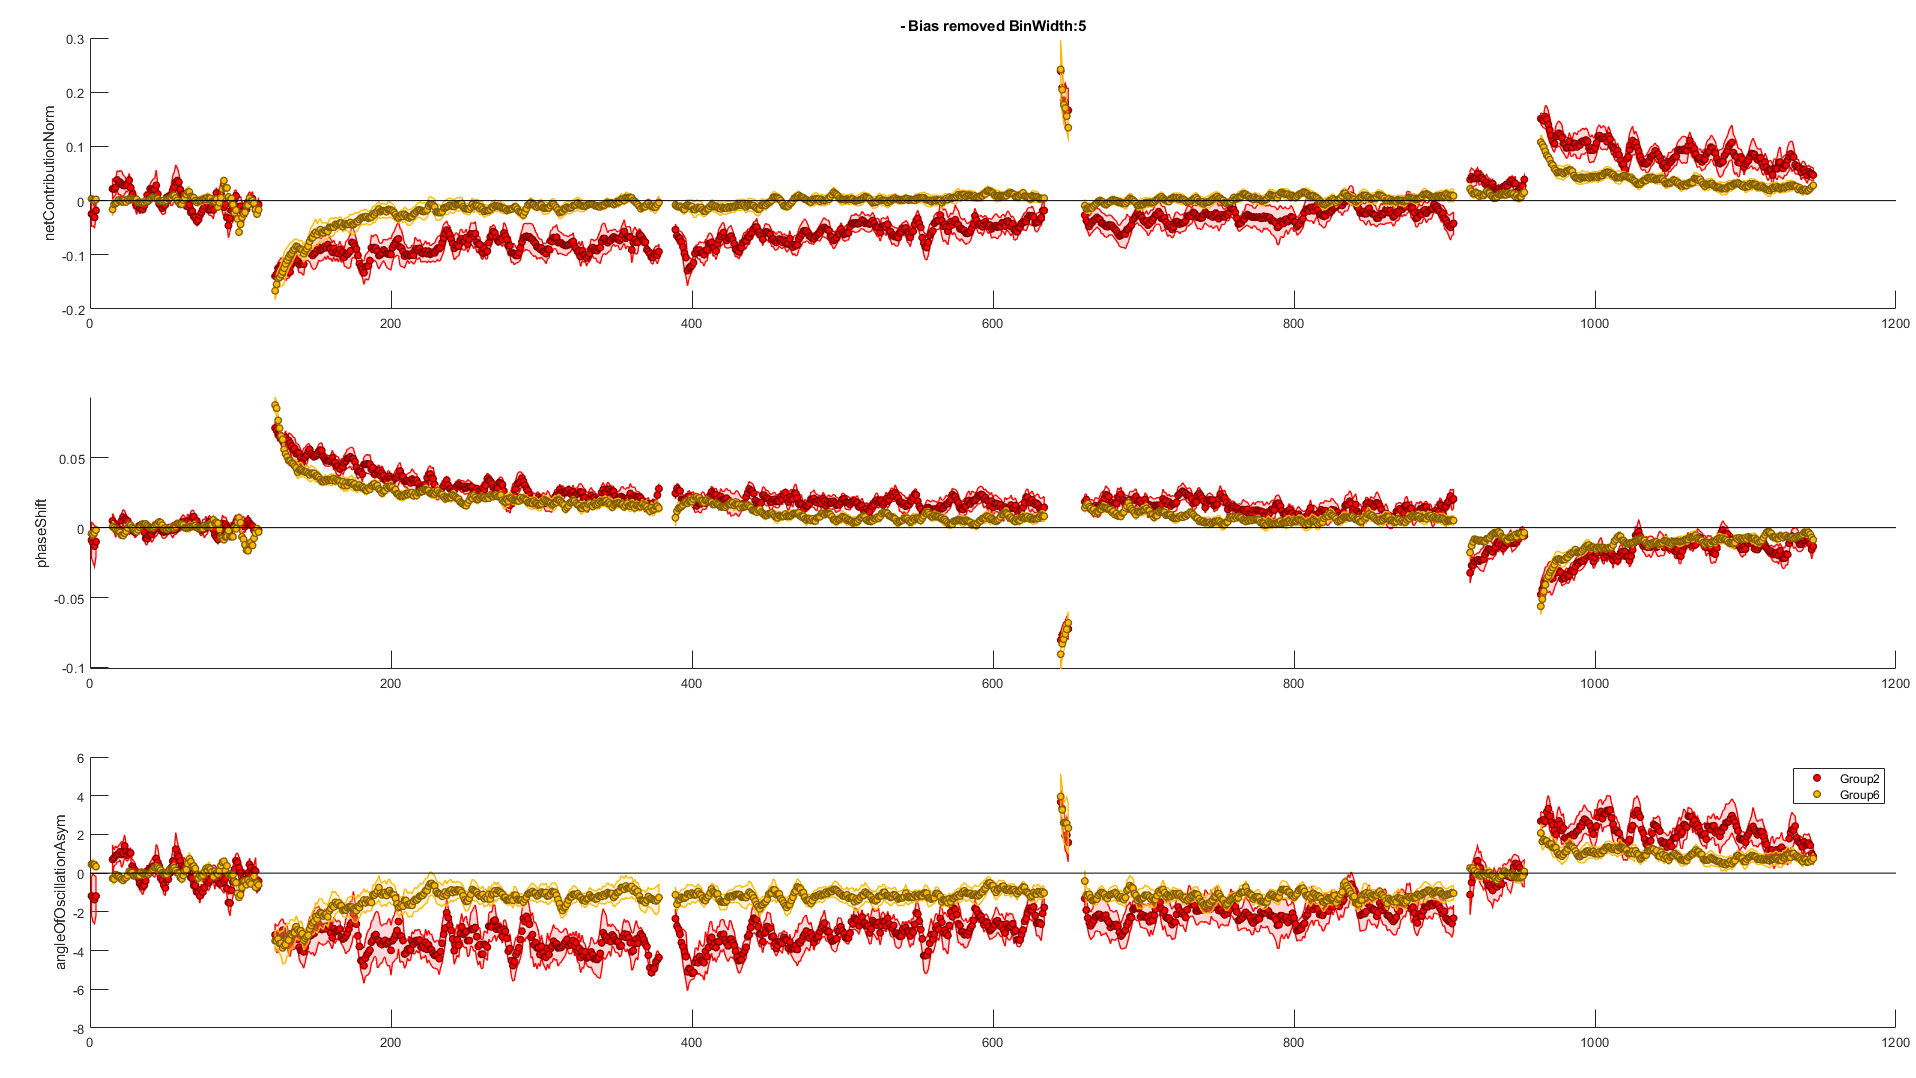

% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix')
% cd(['C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixHipPostion'])
% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLine')
% cd('C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLine')
% cd('C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLine')
% cd('C:\Users\maris\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLineAll')
cd('C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLineAll')

files=what('./'); 
fileList=files.mat;

group=num2str(fileList{2});
load(group)

binwidth=5;
removeBias=1;
alignEndOG=8;
alignEnd=40;
alignIni=235;
TmBaseIni=40;
alignEndOG=[];
alignEnd=[];
alignIni=[];
TmBaseIni=[];
alignEndOG=[];
% OGbaseIni=30;


% % parameters={'stepLengthAsym','netContributionNorm'};
% parameters={'spatialContributionNorm','stepTimeContributionNorm','velocityContributionNorm','netContributionNorm'};
%  parameters={'alphaFast','alphaTemp','alphaSlow'};
parameters={'netContributionNorm','phaseShift','angleOfOscillationAsym'};
% parameters={'alphaAngTemp','alphaAngFast','betaAngSlow','betaAngFast'};
%  parameters={'alphaSlow','alphaFast','Xslow','Xfast'};
% parameters={'angleOfOscillationAsym'};
cond={'OGBase','TMBase','Adaptation1','Adaptation2','Catch','Readaptation','OGpost','TMpost'};
%  cond={'OGBase','TMBase','Adaptation1','Adaptation2','Readaptation','OGpost','TMpost'};
% cond={'OGBase','OGpost'};
% cond={'TMBase','Adaptation1','Adaptation2','Catch','Readaptation','TMpost'};
% cond={'OGBase','TMBase','OGpost','TMpost'};


TimecourseDM(ConcMatrix,parameters,cond,binwidth,0,removeBias,alignEndOG,alignIni,alignEnd,TmBaseIni);


% patch([123 123, 530 530],[-.2 .3, .3 -.2],[1 1 1],'FaceAlpha',0.3)


% if removeBias
% print(['GroupsAvgBiasRemovedBinWidth' num2str(binwidth) Type{1}],'-dpng')
% else
% print(['GroupsAvgBinWidth' num2str(binwidth) Type{1}],'-dpng')  
% end

## BAR PLOT RESULTS

% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix')
% cd(['C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixHipPostion'])
% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLine')
% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\ConcGRoups\Line')
% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\ConcGRoups\hipPosition')
% cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLine')
%  cd(['C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixHipPostion'])
% cd('C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLine')
% cd('C:\Users\maris\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLineAll')
% cd(['C:\Users\maris\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixHipPostion'])

% cd('C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLineAll')
cd('C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLineAll')


files=what('./'); 
fileList=files.mat;

group=num2str(fileList{end-1});
load(group)


removeBias=1;
maxPerturb=1;
indivFlag=1;
plotFlag=0;
maxParam={'PS'};
removeOutlier=1;
mergeG=0;
% parameters={'spatialContributionNorm','stepTimeContributionNorm','velocityContributionNorm','netContributionNorm'};
% parameters={'spatialContributionNorm'};
% parameters={'stepTimeContributionNorm'};.3

% parameters={'angleOfOscillationAsym','phaseShift'};
% parameters={'angleOfOscillationAsym'};
parameters={'phaseShift'};
% parameters={'netContributionNorm'};
% parameters={'alphaAngTemp','alphaAngFast','betaAngSlow','betaAngFast'};
cond={'OGBase', 'TMBase','Adaptation1','Catch','Readaptation','OGpost','TMpost','Adaptation2'};

results = getResultsDM(ConcMatrix,parameters,[],maxPerturb,plotFlag,indivFlag,removeBias,cond,maxParam,removeOutlier,mergeG);
% VarResults = getResultsVarianceDM(ConcMatrix,parameters,[],0,plotFlag,indivFlag,removeBias,cond,maxParam,removeOutlier,mergeG);

% barGroups(ConcMatrix,results,groups,params,epochs,indivFlag,colorOrder,mode)
% if maxPerturb==0 && removeBias==1
% save('MaxResultsWOBias','results') 
% elseif removeBias==1 && maxPerturb==0
% save('AvgResultsWOBias','results') 
% elseif maxPerturb==1
% save('MaxResults','results')    
% elseif removeBias==0 && maxPerturb==0
% save('AvgResults','results')    
% end

## OG_study ALL CONDITION ALL GROUPS

cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\OGStudy')

Error using cd
Cannot CD to C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\OGStudy (Name is nonexistent or not a directory).

files=what('./'); 
fileList=files.mat;

group=num2str(fileList{1});
load(group)
adaptDataList=OGStudy.YoungAbrupt;


params={'spatialContributionNorm2','stepTimeContributionNorm2','velocityContributionNorm2','netContributionNorm2'};
% params={'alphaSlow','alphaFast'};

conditions={'OG base','TM base','adaptation','catch','re-adaptation','OG post','TM post'};
binwidth=5;
trialMarkerFlag=0;
indivFlag=0;
indivSubs=[];
colorOrder=0;
biofeedback=0;
removeBiasFlag=0;

%  plotAvgTimeCourse(adaptDataList,params,conditions,binwidth)
plotAvgTimeCourse(adaptDataList,params,conditions,binwidth,trialMarkerFlag,indivFlag,indivSubs,colorOrder,biofeedback,removeBiasFlag)

## OG_study BAR PLOT RESULTS

cd('C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\OGStudy')

Error using cd
Cannot CD to C:\Users\dum5\Desktop\KidsStudy\Data\Kids_paper\SMatrix\OGStudy (Name is nonexistent or not a directory).

files=what('./'); 
fileList=files.mat;

group=num2str(fileList{1});
load(group)
adaptDataList=OGStudy;
% adaptDataList=OGStudy.YoungAbrupt;

removeBias=0;
maxPerturb=0;
indivFlag=1;
plotFlag=0;
parameters={'spatialContributionNorm2','stepTimeContributionNorm2','velocityContributionNorm2','netContributionNorm2'};
% parameters={'spatialContributionNorm'};
% parameters={'stepTimeContributionNorm'};

results=getResults(adaptDataList,parameters,{'YoungAbrupt'},maxPerturb,plotFlag,indivFlag,removeBias);